# Setup

addpath('../LabFiles/Functions/')
addpath('../LabFiles/Images-m/')

# K-Means

K = 4;               % number of clusters used
L = 10;              % number of iterations
seed = 14;           % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 1.0;   % image preblurring scale

orange = imread('orange.jpg');
orange = imresize(orange, scale_factor);
Iback = orange;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
orange = imfilter(orange, h);

tic
[ segm, centers ] = kmeans_segm(orange, K, L, seed);

  236.7942  198.9509  112.8372
  239.0846  198.9598  118.1480
  230.2844  202.9599  113.1927
  231.6671  199.0071  124.3909

   52.5132

    8.5639

    2.5384

    1.0814

    0.4238

    0.1723

    0.0655

    0.0213

    0.0036

    0.0023



toc

Elapsed time is 0.151992 seconds.


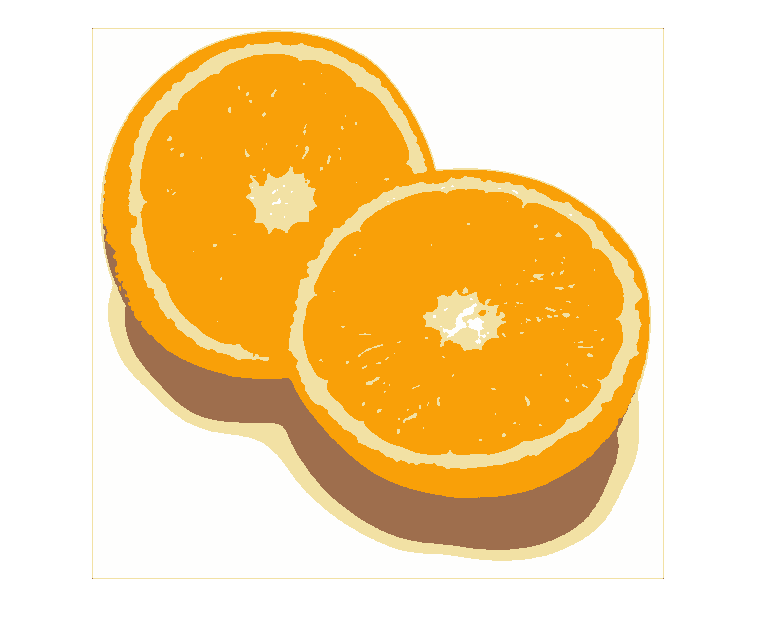

Inew = mean_segments(Iback, segm);
imshow(Inew);

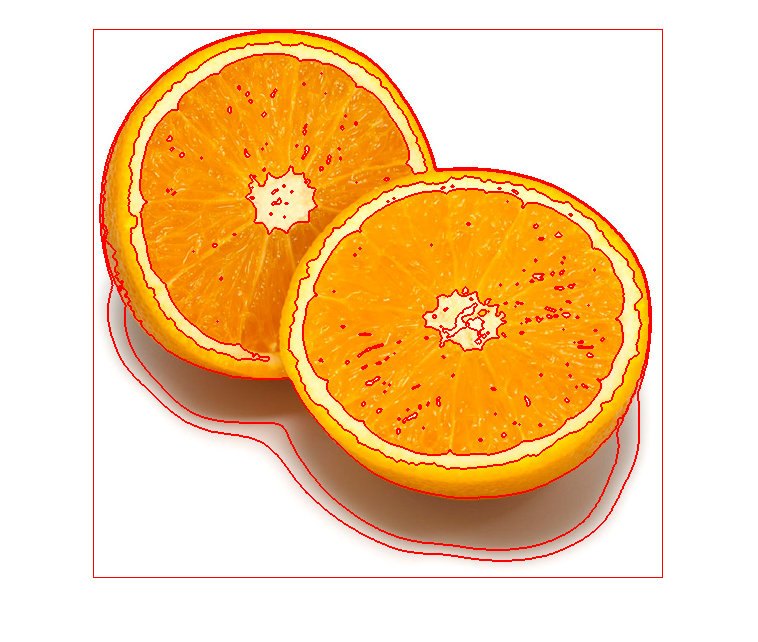

orange = overlay_bounds(Iback, segm);
imshow(orange);


K = 6;               % number of clusters used
L = 20;              % number of iterations
seed = 14;           % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 5.0;   % image preblurring scale

orange = imread('tiger2.jpg');
orange = imresize(orange, scale_factor);
Iback = orange;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
orange = imfilter(orange, h);

[ segm, centers ] = kmeans_segm(orange, K, L, seed);

   85.2919   91.5661   74.1140
  102.0531   81.1729   83.6891
   99.4980   95.2842   83.8317
  101.4425   94.9858   81.5486
   91.8845   86.6017   81.9005
   97.3699  100.6246   90.0110

   22.6815

    7.2777

    3.3796

    2.4837

    2.3739

    2.4397

    2.1805

    1.6502

    1.3079

    1.0578

    0.9098

    0.8251

    0.7348

    0.6557

    0.5587

    0.4688

    0.3831

    0.3269

    0.2646

    0.2291



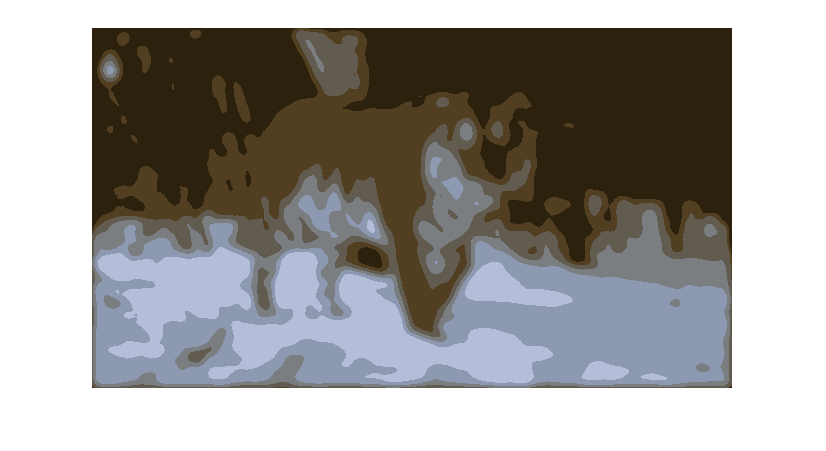


Inew = mean_segments(Iback, segm);
imshow(Inew);

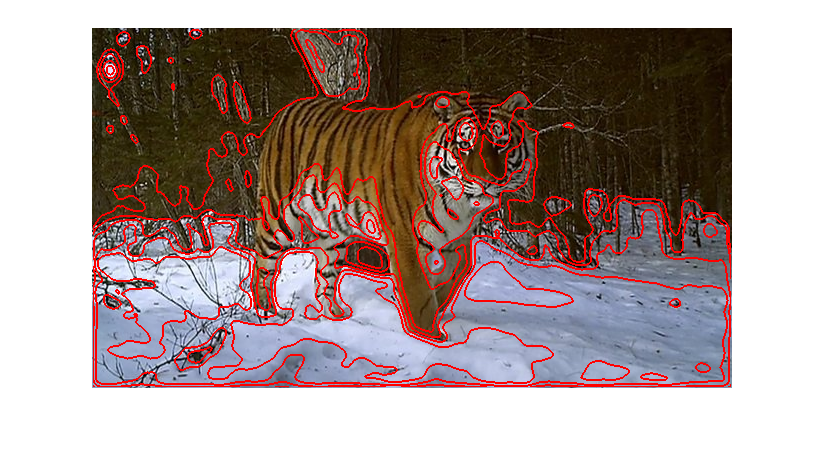

orange = overlay_bounds(Iback, segm);
imshow(orange);

# Mean Shift

scale_factor = 0.9;       % image downscale factor
spatial_bandwidth = 12.0;  % spatial bandwidth
colour_bandwidth = 5.0;   % colour bandwidth
num_iterations = 60;      % number of mean-shift iterations
image_sigma = 5.0;        % image preblurring scale

I = imread('tiger1.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth, num_iterations);

Find colour channels with K-means...
Elapsed time is 0.194709 seconds.
Elapsed time is 0.315385 seconds.
Search for high density points...


Elapsed time is 0.364230 seconds.
Elapsed time is 0.390572 seconds.
Elapsed time is 0.419727 seconds.
Elapsed time is 0.447557 seconds.
Elapsed time is 0.473131 seconds.
Elapsed time is 0.503655 seconds.
Elapsed time is 0.559710 seconds.
Elapsed time is 0.591780 seconds.
Elapsed time is 0.619970 seconds.
Elapsed time is 0.652664 seconds.
Elapsed time is 0.684196 seconds.
Elapsed time is 0.718087 seconds.
Elapsed time is 0.746932 seconds.
Elapsed time is 0.772447 seconds.
Elapsed time is 0.801778 seconds.
Elapsed time is 0.833459 seconds.
Elapsed time is 0.861501 seconds.
Elapsed time is 0.887853 seconds.
Elapsed time is 0.916844 seconds.
Elapsed time is 0.950378 seconds.
Elapsed time is 0.976135 seconds.
Elapsed time is 1.004696 seconds.
Elapsed time is 1.035317 seconds.
Elapsed time is 1.063693 seconds.
Elapsed time is 1.093873 seconds.
Elapsed time is 1.123328 seconds.
Elapsed time is 1.149912 seconds.
Elapsed time is 1.177491 seconds.
Elapsed time is 1.207835 seconds.
Elapsed time i

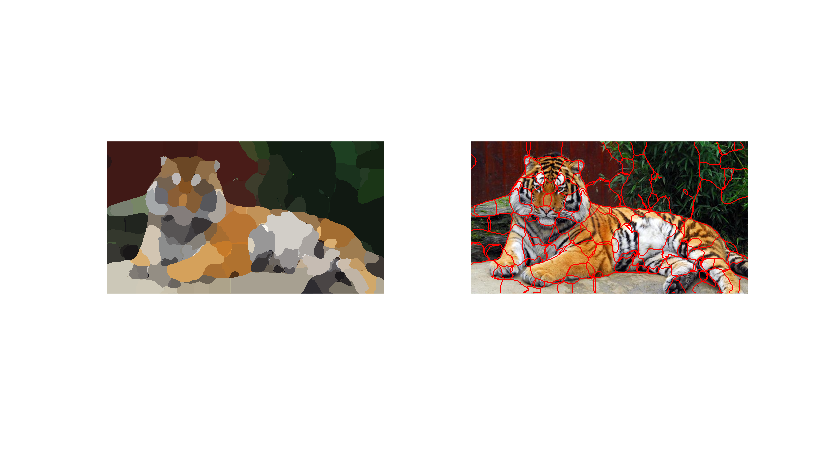

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/meanshift1.png')
%imwrite(I,'result/meanshift2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(I);

scale_factor = 0.9;       % image downscale factor
spatial_bandwidth = 7.0;  % spatial bandwidth
colour_bandwidth = 3.5;   % colour bandwidth
num_iterations = 60;      % number of mean-shift iterations
image_sigma = 3.0;        % image preblurring scale

I = imread('orange.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth, num_iterations);

Find colour channels with K-means...
Elapsed time is 0.270778 seconds.
Elapsed time is 0.454931 seconds.
Search for high density points...


Elapsed time is 0.522436 seconds.
Elapsed time is 0.562248 seconds.
Elapsed time is 0.605675 seconds.
Elapsed time is 0.643781 seconds.
Elapsed time is 0.683501 seconds.
Elapsed time is 0.741277 seconds.
Elapsed time is 0.808664 seconds.
Elapsed time is 0.850560 seconds.
Elapsed time is 0.895676 seconds.
Elapsed time is 0.943076 seconds.
Elapsed time is 0.983764 seconds.
Elapsed time is 1.021923 seconds.
Elapsed time is 1.066125 seconds.
Elapsed time is 1.112857 seconds.
Elapsed time is 1.155582 seconds.
Elapsed time is 1.197532 seconds.
Elapsed time is 1.242688 seconds.
Elapsed time is 1.284891 seconds.
Elapsed time is 1.328016 seconds.
Elapsed time is 1.370474 seconds.
Elapsed time is 1.408913 seconds.
Elapsed time is 1.446916 seconds.
Elapsed time is 1.487768 seconds.
Elapsed time is 1.530732 seconds.
Elapsed time is 1.574821 seconds.
Elapsed time is 1.619280 seconds.
Elapsed time is 1.660141 seconds.
Elapsed time is 1.699769 seconds.
Elapsed time is 1.746091 seconds.
Elapsed time i

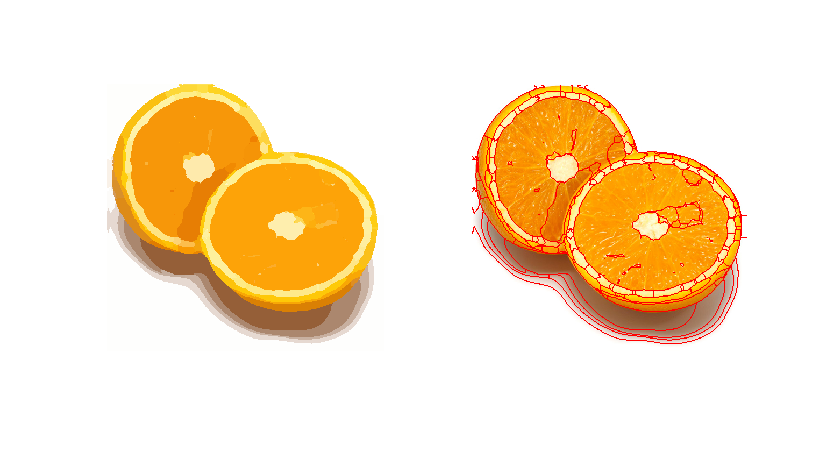

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/meanshift1.png')
%imwrite(I,'result/meanshift2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(I);

scale_factor = 0.9;       % image downscale factor
spatial_bandwidth = 7.0;  % spatial bandwidth
colour_bandwidth = 7.0;   % colour bandwidth
num_iterations = 60;      % number of mean-shift iterations
image_sigma = 8.0;        % image preblurring scale

I = imread('tiger2.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = mean_shift_segm(I, spatial_bandwidth, colour_bandwidth, num_iterations);

Find colour channels with K-means...
Elapsed time is 0.203918 seconds.
Elapsed time is 0.339935 seconds.
Search for high density points...


Elapsed time is 0.388323 seconds.
Elapsed time is 0.411814 seconds.
Elapsed time is 0.437208 seconds.
Elapsed time is 0.465339 seconds.
Elapsed time is 0.497873 seconds.
Elapsed time is 0.527374 seconds.
Elapsed time is 0.578082 seconds.
Elapsed time is 0.608584 seconds.
Elapsed time is 0.636511 seconds.
Elapsed time is 0.665583 seconds.
Elapsed time is 0.700864 seconds.
Elapsed time is 0.732036 seconds.
Elapsed time is 0.761189 seconds.
Elapsed time is 0.790594 seconds.
Elapsed time is 0.819964 seconds.
Elapsed time is 0.850276 seconds.
Elapsed time is 0.878379 seconds.
Elapsed time is 0.906620 seconds.
Elapsed time is 0.936258 seconds.
Elapsed time is 0.967102 seconds.
Elapsed time is 0.996165 seconds.
Elapsed time is 1.027202 seconds.
Elapsed time is 1.056018 seconds.
Elapsed time is 1.090446 seconds.
Elapsed time is 1.119025 seconds.
Elapsed time is 1.147448 seconds.
Elapsed time is 1.176299 seconds.
Elapsed time is 1.206706 seconds.
Elapsed time is 1.235780 seconds.
Elapsed time i

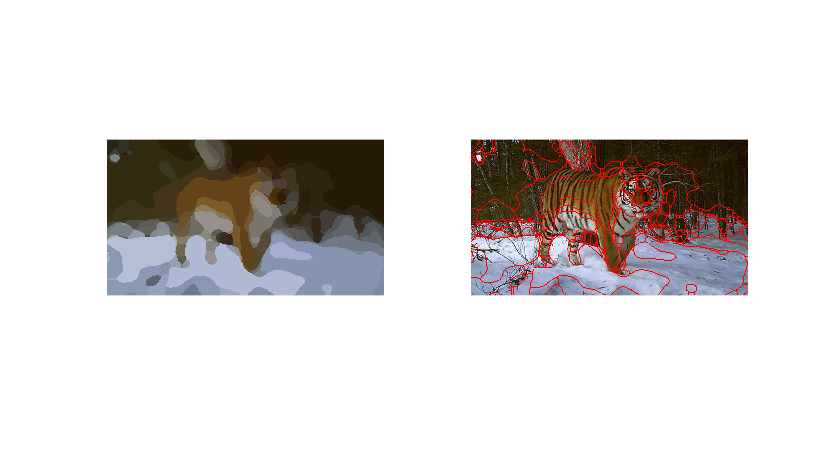

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/meanshift1.png')
%imwrite(I,'result/meanshift2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(I);

# Ncut

colour_bandwidth = 20.0; % color bandwidth
radius = 20;              % maximum neighbourhood distance
ncuts_thresh = 0.2;      % cutting threshold
min_area = 200;          % minimum area of segment
max_depth = 8;           % maximum splitting depth
scale_factor = 0.4;      % image downscale factor
image_sigma = 2.0;       % image preblurring scale

I = imread('tiger2.jpg');
I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

segm = norm_cuts_segm(I, colour_bandwidth, radius, ncuts_thresh, min_area, max_depth);

Compute affinity matrix...
Elapsed time is 8.270181 seconds.
Solve eigenvalue problems to find partitions...
Cutting ncut=0.011 sizes=(18455,18409)
Cutting ncut=0.034 sizes=(6379,12076)
Cutting ncut=0.066 sizes=(3610,2769)
Cutting ncut=0.208 sizes=(2016,1594)
Cutting ncut=0.053 sizes=(2096,673)
Cutting ncut=0.178 sizes=(1388,708)
Cutting ncut=0.201 sizes=(425,963)
Cutting ncut=0.420 sizes=(470,238)
Cutting ncut=0.355 sizes=(234,439)
Cutting ncut=0.047 sizes=(3475,8601)
Cutting ncut=0.196 sizes=(423,3052)
Cutting ncut=0.293 sizes=(186,237)
Cutting ncut=0.190 sizes=(2535,517)
Cutting ncut=0.215 sizes=(752,1783)
Cutting ncut=0.370 sizes=(278,239)
Cutting ncut=0.397 sizes=(88,8513)
Cutting ncut=0.048 sizes=(1635,16774)
Cutting ncut=0.323 sizes=(1223,412)
Cutting ncut=0.112 sizes=(5070,11704)
Cutting ncut=0.148 sizes=(5005,65)
Cutting ncut=0.140 sizes=(8312,3392)
Cutting ncut=0.194 sizes=(5411,2901)
Cutting ncut=0.233 sizes=(3804,1607)
Cutting ncut=0.298 sizes=(513,2388)
Cutting ncut=0.085 

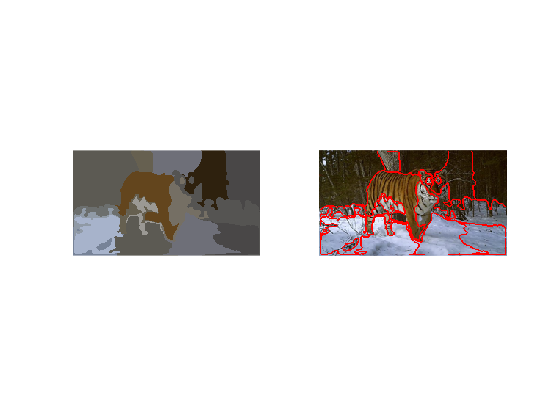

Inew = mean_segments(Iback, segm);
I = overlay_bounds(Iback, segm);
%imwrite(Inew,'result/normcuts1.png')
%imwrite(I,'result/normcuts2.png')
subplot(1,2,1); imshow(Inew);
subplot(1,2,2); imshow(I);